clear all
close all

addpath("Immagini/05_slantedEdge")

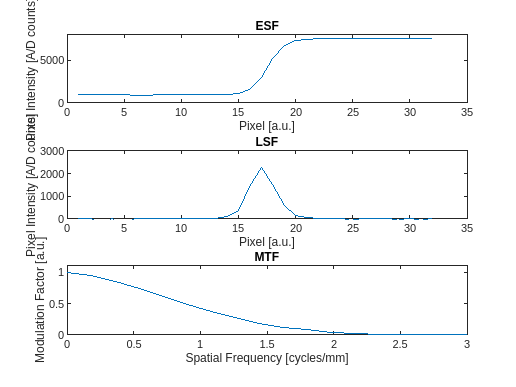

Fiji_ESF = csvread("ImageJ_ESF.csv", 1);
Fiji_LSF = csvread("ImageJ_LSF.csv", 1);
Fiji_MTF = csvread("ImageJ_MTF.csv", 1);

subplot(3,1,1)
plot(Fiji_ESF(:,1), Fiji_ESF(:,2))
title("ESF")
ylim([0 8000])
ylabel("Pixel Intensity [A/D counts]")
xlabel("Pixel [a.u.]")

subplot(3,1,2)
plot(Fiji_LSF(:,1), Fiji_LSF(:,2))
title("LSF")
ylim([0 3000])
ylabel("Pixel Intensity [A/D counts]")
xlabel("Pixel [a.u.]")

subplot(3,1,3)
plot(Fiji_MTF(:,1)*5.6, Fiji_MTF(:,2))
title("MTF")
ylim([0 1.1])
xlim([0 3])
ylabel("Modulation Factor [a.u.]")
xlabel("Spatial Frequency [cycles/mm]")